# Task 3 - Number plate recognition

## Pre-processing

figure;

### Read images and turn them to grayscale

img_path = "images/final/task_3/";

image1 = imread(img_path + "example_number_plate.png");
subplot(2, 2, 1); imshow(image1); title("Original Image");

img1gray = rgb2gray(image1);
subplot(2, 2, 2); imshow(img1gray); title("1. Grayscale");

### Noise removal

% Here I guess we could use imbilatfilt to filter it 
% bilaterally like in the documentation.
img1med = medfilt2(img1gray);
subplot(2, 2, 3); imshow(img1med); title("2. Noise Removal (Median Filter)");

### Contrast Enhancement 

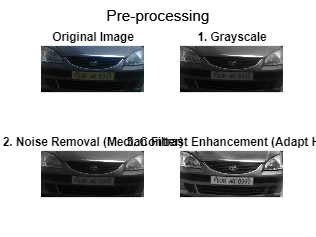

img1cont = adapthisteq(img1med);
subplot(2, 2, 4); imshow(img1cont); title("3. Contrast Enhancement (Adapt Hist)");

sgtitle("Pre-processing");

## Morphological Opening and Image Subtraction Operations

figure;

### Opening with 'disk'

se = strel('disk',15);
img1open = imopen(img1cont,se);
subplot(1, 3, 1); imshow(img1open); title("4. Disk Opening");

### Subtraction from enhanced image

img1sub = imsubtract(img1cont, img1open);
subplot(1, 3, 2); imshow(img1sub); title("5. Substract from Enhanced Image");

## Image binarization

% Find grayscale threshold and binarize
bins = 19;
[counts,x] = imhist(img1sub, bins);
g_thresh = otsuthresh(counts) %graythresh(img1sub)

g_thresh = 0.1667

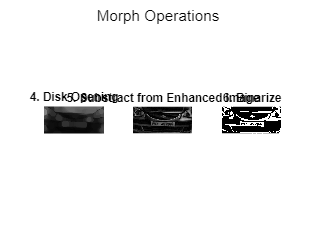


img1bin = imbinarize(img1sub, g_thresh);

%imshowpair(img1bin, img1bin_filled); 
subplot(1, 3, 3); imshow(img1bin); title("6. Binarize");
sgtitle("Morph Operations");

## Creating Mask

figure;

### Detect edges with the Sobel operator

img1edge = edge(img1bin);
subplot(2, 3, 1); imshow(img1edge); title("7. Sobel Edge Detection");

### Candidate plate area detection with morphological operators

#### Dilation

se2 = strel('square', 2);
img1dil = imdilate(img1edge, se2);
subplot(2, 3, 2); imshow(img1dil); title("8. Square Dilation");

#### Filling holes

img1fill = imfill(img1dil, 'holes');
subplot(2, 3, 3); imshow(img1fill); title("9. Fill Holes");

#### Opening

se3 = strel('square',22);
img1open = imopen(img1fill, se3);
subplot(2, 3, 4); imshow(img1open); title("10. Square Opening");

#### Remove smaller objects

img1clean = bwareaopen(img1open, 800);
subplot(2, 3, 5); imshow(img1clean); title("11. Removed small objects");

### Apply Mask

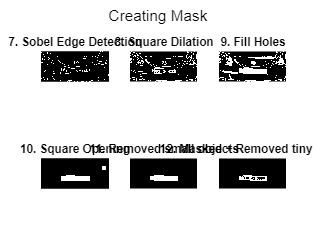

img1bin(~img1clean) = 0;
%subplot(2, 3, 6); imshow(img1bin); title("Masked Image");

% Remove tiny holes based on size (screws at the top of plate)
img1bin_filled = ~bwareaopen(~img1bin, 20);
subplot(2, 3, 6); imshow(img1bin_filled); title("12. Masked + Removed tiny holes");

sgtitle("Creating Mask");

## OCR

Should make it only check for 

- Letters (Language) for the first 2 letters

- Numeric for the following 2 letters

- Letters for the middle 2 letters

- Numeric digits for the last 4 digits

img_ocr = img1bin_filled;

% By default the ocr function's TextLayout will return a separate word for each set of
% letters that are separated by some space.
first_2_letters = "[N/A]";
middle_2_letters = "[N/A]";
ocr_words_letters = ocr(img_ocr, 'CharacterSet', 'A':'Z');
if (size(ocr_words_letters) >= 1)
    first_2_letters = ocr_words_letters.Words{1}(1:2);
    middle_2_letters = ocr_words_letters.Words{2};
end

first_2_digits = "[N/A]";
last_4_digits = "[N/A]";
ocr_words_digits = ocr(img_ocr, 'CharacterSet', '0123456789');
if (size(ocr_words_digits) > 0)
    first_2_digits = ocr_words_digits.Words{1}(3:4);
    last_4_digits = ocr_words_digits.Words{3};
end

disp(first_2_letters + "" + first_2_digits + " " + middle_2_letters + " " + last_4_digits);

PB08 AQ 0999



fclose('all');